# **PI VECTORIAL Y OBSERVADOR DE ESTADO**

**SEGUIMIENTO A LA REFERENCIA Y ANULA EL CERO DE EL SISTEMA EN LAZO ABIERTO**

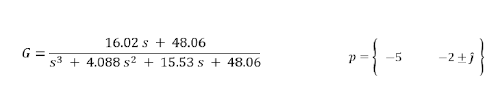

s=tf('s');
G=((16.02*s)+48.06)/(s^3+4.088*s^2+15.53*s+48.06)
zpk(G) %El sistema tiene un cero en (s+3)
pole(G)

Ge=ss(G)
A=Ge.a; B=Ge.b;C=Ge.c;D=Ge.d; %Separamos nuestras matrices
order(G)
Mc=rank(ctrb(A,B))

%Aa=[Ge.a,[0;0];-Ge.c,0] %Agreamos los cero adicional para el pi
%Ba=[Ge.b;0]
%Ca= [Ge.c 0]

%Polos 
P=[-3 -2+1i -2-1i ]

Pa=[-5 -2+1i -2-1i ] %Polos para ki

Pob=P(1:3)*10 %Polos para observador
L=acker(A',C',Pob)' %Vector columna L

Ka=acker(A,B,Pa);     %Hallamos los valores de k
K=Ka(1:end-1)           %Valores de k
ki=-Ka(end)      

Ge_ci= ss(Ge.a-Ge.a*Ka,Ge.a,Ge.c,0);
Ge_ci=tf(Ge_ci)
Tci=feedback(Ge_ci*ki/s,1);
figure();
step(Tci),legend